%% Minimal 3-Channel Bandpower SVM
% This script:
% 1. Loads the C3, Cz and C4 epoch data
% 2. Extracts mu and beta power from each channel
% 3. Creates 6 understandable features
% 4. Trains a linear SVM
% 5. Calculates classification accuracy

clear;
close all;
clc;

%% Step 1: Set project path

basePath = '/Users/kandulasatwika/Desktop/400_BCI_MATLAB';


%% Step 2: Load the 3-channel epoch data

load(fullfile(basePath, ...
    'Outputs', ...
    'Filtered data', ...
    'combined_epochs_3channels.mat'));

disp('Three-channel EEG epoch data loaded.');

Three-channel EEG epoch data loaded.



disp(['Left data shape:  ', mat2str(size(all_left))]);

Left data shape:  [3 640 230]


disp(['Right data shape: ', mat2str(size(all_right))]);

Right data shape: [3 640 220]


disp(['Rest data shape:  ', mat2str(size(all_rest))]);

Rest data shape:  [3 640 420]



disp('Selected channels:');

Selected channels:


disp(selectedChannels');

    {'C3..'}
    {'Cz..'}
    {'C4..'}





%% Step 3: Balance the three classes

% The classes may have different numbers of epochs.
% Use the smallest class size for all three classes.

numberOfEpochs = min([size(all_left,3), ...
                      size(all_right,3), ...
                      size(all_rest,3)]);

disp(['Epochs used per class: ', ...
    num2str(numberOfEpochs)]);

Epochs used per class: 220



% Use the same random selection every time.
rng(42);

leftEpochIndices = randperm( ...
    size(all_left,3), numberOfEpochs);

rightEpochIndices = randperm( ...
    size(all_right,3), numberOfEpochs);

restEpochIndices = randperm( ...
    size(all_rest,3), numberOfEpochs);

% Select balanced epochs.
leftData = all_left(:,:,leftEpochIndices);

rightData = all_right(:,:,rightEpochIndices);

restData = all_rest(:,:,restEpochIndices);


%% Step 4: Extract mu and beta features

% Each channel gives two features:
%
% Mu power   = 8–12 Hz
% Beta power = 13–30 Hz
%
% C3, Cz and C4:
%
% 3 channels × 2 frequency bands = 6 features

leftFeatures = extract_motor_bandpower( ...
    leftData, samplingRate);

rightFeatures = extract_motor_bandpower( ...
    rightData, samplingRate);

restFeatures = extract_motor_bandpower( ...
    restData, samplingRate);

disp(['Left feature shape:  ', ...
    mat2str(size(leftFeatures))]);

Left feature shape:  [220 6]



disp(['Right feature shape: ', ...
    mat2str(size(rightFeatures))]);

Right feature shape: [220 6]



disp(['Rest feature shape:  ', ...
    mat2str(size(restFeatures))]);

Rest feature shape:  [220 6]




%% Step 5: Define the six feature names

featureNames = ["C3_mu", "C3_beta", ...
                "Cz_mu", "Cz_beta", ...
                "C4_mu", "C4_beta"];

disp('Features used:');

Features used:


disp(featureNames');

    "C3_mu"
    "C3_beta"
    "Cz_mu"
    "Cz_beta"
    "C4_mu"
    "C4_beta"





%% Step 6: Combine all features

X = [leftFeatures;
     rightFeatures;
     restFeatures];

% Create labels for each epoch.
Y = [repmat("LEFT", numberOfEpochs, 1);
     repmat("RIGHT", numberOfEpochs, 1);
     repmat("REST", numberOfEpochs, 1)];

Y = categorical(Y);

disp(['Final feature matrix shape: ', ...
    mat2str(size(X))]);

Final feature matrix shape: [660 6]



% The number of columns should be 6.


%% Step 7: Split into training and testing data

% Use 80% for training and 20% for testing.

cv = cvpartition(Y, ...
    'HoldOut', 0.20);

trainingIndices = training(cv);

testingIndices = test(cv);

XTrain = X(trainingIndices,:);

YTrain = Y(trainingIndices);

XTest = X(testingIndices,:);

YTest = Y(testingIndices);

disp(['Training samples: ', ...
    num2str(size(XTrain,1))]);

Training samples: 528



disp(['Testing samples: ', ...
    num2str(size(XTest,1))]);

Testing samples: 132




%% Step 8: Create the linear SVM

% fitcecoc creates a multiclass classifier.
% A linear SVM is used because it is easier to interpret.

svmTemplate = templateSVM( ...
    'KernelFunction', 'linear', ...
    'Standardize', true);

minimalSVMModel = fitcecoc( ...
    XTrain, ...
    YTrain, ...
    'Learners', svmTemplate, ...
    'Coding', 'onevsone');

disp('Minimal 6-feature SVM trained successfully.');

Minimal 6-feature SVM trained successfully.




%% Step 9: Test the model

predictedLabels = predict( ...
    minimalSVMModel, XTest);

minimalAccuracy = mean( ...
    predictedLabels == YTest) * 100;

fprintf('\nMinimal 3-channel SVM accuracy: %.2f%%\n', ...
    minimalAccuracy);


Minimal 3-channel SVM accuracy: 37.12%


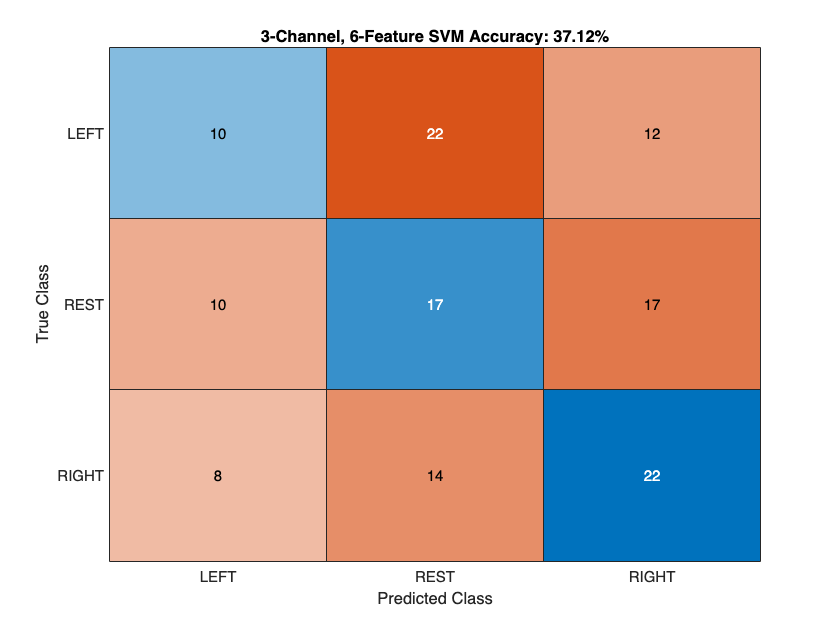



%% Step 10: Display confusion matrix

figure;

confusionchart(YTest, predictedLabels);

title(['3-Channel, 6-Feature SVM Accuracy: ', ...
    num2str(minimalAccuracy, '%.2f'), '%']);



%% Step 11: Display the model information

disp(' ');

disp('=== Minimal Model Summary ===');

=== Minimal Model Summary ===



disp(['Number of channels: ', ...
    num2str(size(all_left,1))]);

Number of channels: 3



disp(['Number of features: ', ...
    num2str(size(X,2))]);

Number of features: 6



disp(['Accuracy: ', ...
    num2str(minimalAccuracy, '%.2f'), '%']);

Accuracy: 37.12%



disp('Channels:');

Channels:


disp(selectedChannels');

    {'C3..'}
    {'Cz..'}
    {'C4..'}




disp('Features:');

Features:


disp(featureNames');

    "C3_mu"
    "C3_beta"
    "Cz_mu"
    "Cz_beta"
    "C4_mu"
    "C4_beta"





%% Step 12: Save the model

save(fullfile(basePath, ...
    'Outputs', ...
    'minimal_3channel_svm_model.mat'), ...
    'minimalSVMModel', ...
    'minimalAccuracy', ...
    'featureNames', ...
    'selectedChannels', ...
    'samplingRate');

disp('Minimal three-channel SVM model saved successfully.');

Minimal three-channel SVM model saved successfully.




%% Local Function: Extract Mu and Beta Power


function features = extract_motor_bandpower(data, samplingRate)

    % Input data shape:
    %
    % channels × time points × epochs

    numberOfChannels = size(data,1);

    numberOfEpochs = size(data,3);

    % Each channel gives two features:
    % mu power and beta power.

    numberOfFeatures = numberOfChannels * 2;

    features = zeros( ...
        numberOfEpochs, numberOfFeatures);


    %% Go through every epoch

    for e = 1:numberOfEpochs

        featurePosition = 1;


        %% Go through every EEG channel

        for c = 1:numberOfChannels

            % Select one EEG signal:
            % one channel from one epoch.

            signal = double(data(c,:,e));


            %% Calculate the power spectral density

            [powerSpectrum, frequencies] = ...
                pwelch(signal, [], [], [], samplingRate);


            %% Calculate mu-band power

            muPower = mean( ...
                powerSpectrum( ...
                frequencies >= 8 & ...
                frequencies <= 12));


            %% Calculate beta-band power

            betaPower = mean( ...
                powerSpectrum( ...
                frequencies >= 13 & ...
                frequencies <= 30));


            %% Save the two features

            features(e,featurePosition) = ...
                log10(muPower + eps);

            features(e,featurePosition + 1) = ...
                log10(betaPower + eps);

            featurePosition = ...
                featurePosition + 2;

        end

    end

end